# TCLab Block Diagram Analysis

**Objective**: Determine the closed loop response of a PI controller to a step change in setpoint. Compare the analytical solution to the closed loop response to a setpoint change.

A TCLab block diagram shows the flow of information in a feedback control system that consists of a sensor, actuator, and controller. Block diagrams are different than a process diagram in that it is a diagram of the flow of information, not necessarily how the pieces of equipment are physically placed as reviewed in the TCLab Controller Assignment. The block diagram is a collection of signals and transfer functions that transform one signal into another. Transfer functions transform an input signal into an output signal. The PI controller ($K_c=2$, $\tau_I=180$) is a transfer function $G_c = K_c\frac{\tau_Is+1}{\tau_Is}$ that tranforms an error signal (input) into a heater value ($Q_1$) (controller output). The process transfer function ($G_p=\frac{0.9}{180s+1}e^{-15s}$) receives the heater value ($Q_1$) as an input and produces a change in temperature 1 ($T_{A1}$) process variable output. The disturbance transfer function ($G_d=\frac{0.3}{180s+1}e^{-15s}$) has an input of temperature 2 ($T_2$) and produces a predicted change in temperature 1 ($T_{B2}$) process variable output. The two temperature outputs are added together as $T_1 = T_{A1}+T_{B1}$. The loop is created with the sensor providing information to the controller as an error (*E=T**SP**-T**1*) between the setpoint and measured value. The P-only controller changes the controller output $Q_1$ to change the temperature $T_1$ and the cycle starts again.

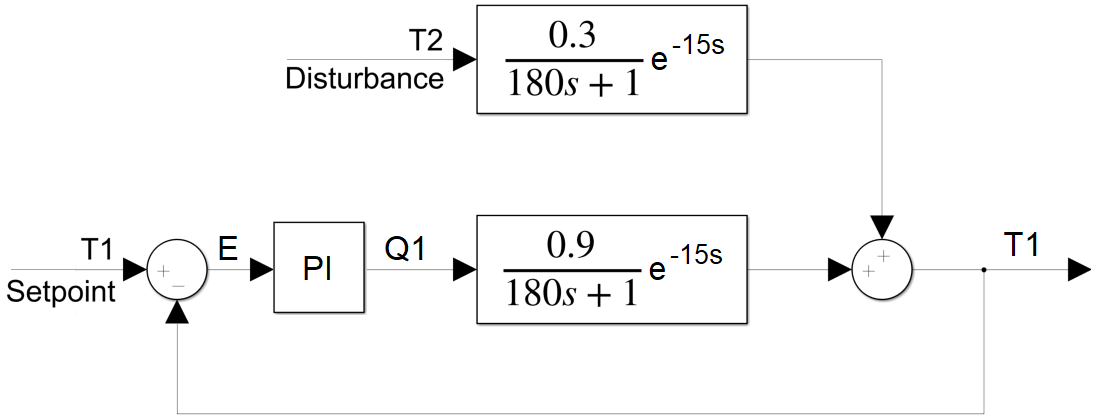

## **Block Diagram Algebra**

The overall transfer function between the disturbance $T_2$ and $T_1$ is derived by algebraically combining the following expressions to eliminate all other signals besides the input and output of interest.


$$E(s) = T_{SP}(s)-T_1(s)$$



$$Q_1(s) = G_c(s) \, E(s) = G_c(s) \, (T_{SP}(s)-T_1(s))$$



$$T_{A1}(s) = G_p(s) \, Q_1(s) = G_c(s) \, G_p(s) \, (T_{SP}(s)-T_1(s))$$



$$T_{B1}(s) = G_d(s) \, T_2(s)$$



$$T_1(s) = T_{A1}(s)+T_{B1}(s) = G_c(s) \, G_p(s) \, (T_{SP}(s)-T_1(s)) + G_d \, T_2(s)$$


In this case, $T_{SP}(s)=0$ because it is assumed that there is no change in the setpoint as the disturbance transfer function is derived.


$$T_1(s) = - G_c(s) \, G_p(s) \, T_1(s) + G_d(s) \, T_2(s)$$


The transfer function is further simplified by collecting all $T_1(s)$ terms to one side and $T_2(s)$ terms to the other.


$$T_1(s) + G_c(s) \, G_p(s) , T_1(s) = G_d \, T_2(s)$$


This simplifies to the overall closed loop transfer function for disturbance changes.


$$\frac{T_1(s)}{T_2(s)} = \frac{G_d(s)}{1+G_c(s)\,G_p(s)} = \frac{\frac{0.3}{180s+1} e^{-15s}}{1+K_c \frac{\tau_I s+1}{\tau_I s} \frac{0.9}{180s+1} e^{-15s}}$$


### **Time-Delay to Polynomial Form**

An inverse Laplace transform is not possible with this transfer function because of the exponential terms. To compute an analytical solution to a step input, a Taylor series approximation or Padé approximation of $e^{(-15s)}$ with the first 2 or 3 terms are typically used to return to polynomial form.

#### *Padé Approximation for exp(x)*


$$\exp(x) \approx \frac{1+\frac{1}{2}x+\frac{1}{9}x^2}{1-\frac{1}{2}x+\frac{1}{9}x^2}$$


Two terms are selected to approximate the dead-time. Additional terms improve the accuracy of the approximation but also increase the order of the polynomial.


$$\exp(-15s) \approx \frac{1-7.5 s}{1+7.5 s}$$


### Taylor Series Approximation for exp(x)


$$\exp(x) \approx \sum_{n=0}^{\infty}\frac{x^n}{n!} = 1+x+\frac{x^2}{2!}+\frac{x^3}{3!}+\dots$$


The exponential is first place in the denominator and two terms are selected to approximate the dead-time.


$$e^{-15s} = \frac{1}{e^{15s}} \approx \frac{1}{15s+1}$$


The Taylor series approximation is used for this example. The polynomial form of the transfer function is used for the analytical solution. The PI controller rejects the disturbance

## **Analytic Solution to PI Controller Response to **$+20^\circ\text{C }T_2$** Disturbance**

The transfer function below converts a $T_2$ disturbance (input) to the resulting $T_1$ (output).


$$\frac{T_1(s)}{T_2(s)} = \frac{G_d(s)}{1+G_c(s)\,G_p(s)} = \frac{\frac{0.3}{180s+1} e^{-15s}}{1+K_c \frac{\tau_I s+1}{\tau_I s} \frac{0.9}{180s+1} e^{-15s}}$$


Using


$$T(t) = \left(1.14 e^{0.0178t} - 7.97 e^{0.0600t} + 6.83 e^{0.067t}\right) e^{-0.072t} S(t-1)$$


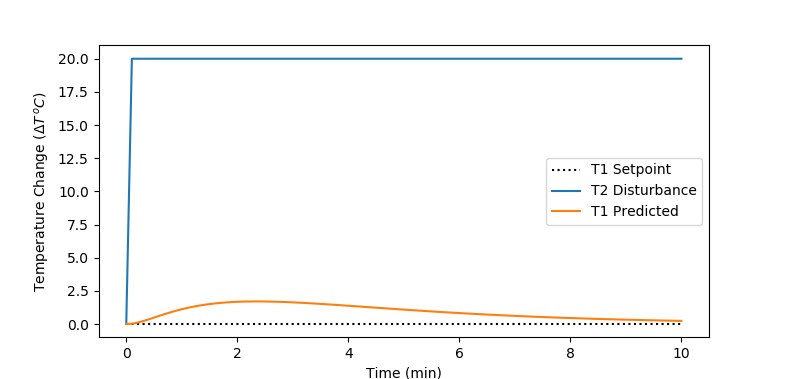

Create symbolic variables

syms s t x y z

Define Input ($T_2$)

T2 = 20/s * exp(-s)

Define Transfer Functions

Kc = 2.0
tauI = 180.0
Gc = Kc * (tauI*s+1)/(tauI*s)
delay = 1/(15*s+1) % Taylor series approximation of delay
Gd = delay * 0.3/(180*s+1)
Gp = delay * 0.9/(180*s+1)

Calculate closed loop response: $\frac{\text{Disturbance gain}}{1+\text{Product of Loop Gains}}$

Gc = Gd/(1+Gc*Gp)

Calculate $T_1$ response

T1 = Gc * T2

Perform an inverse Laplace transform on both the input and output

t1(t) = ilaplace(T1, s, t)
t2(t) = ilaplace(T2, s, t)

Create time array and *substitute* the array in to the symbolic inverse Laplace transform. Then, use double to evaluate the symbolic solutions in decimal form

t_ = linspace(0, 600, 101)
t1_plot = double(subs(t1, t, t_))
t2_plot = double(subs(t2, t, t_))

Finally, plot the solution

figure()
plot([0,10], [0, 0], 'k:', "DisplayName","T1 Setpoint")
hold on
plot(t_/60, t1_plot, 'r-', "DisplayName","T1 Predicted")
hold on
plot(t_/60, t2_plot, 'b-', "DisplayName","T2 Disturbance")
xlabel('Time (min)')
ylabel('Temperature')
ylim([-2, 22])
legend('Location',"best")

## ASSIGNMENT: Compute $T_1$ Through to a $+20^\circ\text{C}$ Setpoint Change

Using the above as an example, calculate the closed loop transfer function for a PI controller between the other input (setpoint $T_{SP}$) and the output ($T_1$). Compute the analytical solution for $T_1$ and show predicted and measured values for a PI controller setpoint change from $23^\circ\text{C}$ to $43^\circ\text{C$. Save the array of predicted temperatures as `T1Pred`. Then, use the PI Test Script to show the analytical and measured values for the closed loop control, modifying the line for the predicted temperature. 

To perform this assignment, you will need to perform transfer function algebra to create a transfer function of the form $\frac{T_1(s)}{T_{SP}(s)$. Afterward, the process of creating the transfer function symbolically, inverse Laplace Transform, and evaluation will be very similar to the process above.

viewSolution(false)

Compute $T_1$analytically through evaluation of transfer functions below

Run the following script to run the step test with the TCLab and Plot both the analytical and experimental results

tmp = matlab.desktop.editor.getActive;
directory = fileparts(tmp.Filename);
filename = "L12_TCLab_data.csv";
absolute_path = fullfile(directory, filename);
try % try to read from file first
    A = readmatrix(absolute_path)
    tm_tclab = A(:,1);
    Q1 = A(:,2);
    T1 = A(:,3);
    disp('TCLab Data read from file')
catch

    Kc = 1/0.9
    TauI = 175.0
    
    % Initialize Arrays
    n = 600;
    tm_tclab = zeros(n,1); 
    T1 = ones(n, 1)*23.0;
    Q1 = zeros(n,1);
    E1 = zeros(n,1);
    IE1 = zeros(n,1);
    SP1 = ones(n, 1)*23.0;
    SP1(1:end) = 43.0;  % step setpoint from 23.0 to 43.0 degC
    
    % connect to TCLab
    lab = tclab;
    
    Q1_bias = 0.0;
    tic
    for i=2:n  
        tm_tclab(i) = toc;
        dt = tm_tclab(i) - tm_tclab(i-1);
        T1(i) = lab.T1;
        E1(i) = SP1(i) - T1(i); 
        IE1(i) = IE1(i-1) + E1(i) * dt; 
        Q1(i) = Q1_bias+Kc*E1(i)+Kc/TauI*IE1(i);   
        if Q1(i) > 100
            IE(i) = IE(i-1) ;
            Q1(i) = 100;
        elseif Q1(i) < 0
            IE(i) = IE(i-1);
            Q1(i) = 0;
        end
        
        % Pass Heater Setting to heater
        lab.Q1(Q1(i));
        
        % Print Status every 20 iterations
        if mod(i,20)==0
            fprintf('Time: %.4g (s) Temperature: %.4g (deg C) Heater: %.4g (%%)\n', toc, T1(i), Q1(i))
        end
        
        % wait for remainder of 1 sec
        pause(1-mod(1-toc,1));
    end
    lab.off
    clear lab
    
    % save
    A = [tm_tclab Q1 T1]
    writematrix(A, absolute_path, 'Delimiter', ',')
end

figure()
subplot(2,1,1)
plot(linspace(0, 600, 101), T1Pred, 'r--', 'DisplayName','T1 Predicted')
hold on
plot(tm_tclab, T1, 'r.', 'DisplayName','T1 Experimental')
hold on
plot([0, tm_tclab(end)], [43, 43], 'k:', "DisplayName",'Setpoint')
legend("Location","best")
ylabel('Temperature (C)')
subplot(2,1,2)
plot(tm_tclab, Q1)
ylabel('Heater Setting')
xlabel('Time(s)')

## Solution

[Solution video]

The overall transfer function between the disturbance $T_{SP}$and $T_1$ is derived by algebraically combining the same expressions to eliminate all other signals besides the input and output of interest.


$$E(s) = T_{SP}(s)-T_1(s)$$



$$Q_1(s) = G_c(s) \, E(s) = G_c(s) \, (T_{SP}(s)-T_1(s))$$



$$T_{A1}(s) = G_p(s) \, Q_1(s) = G_c(s) \, G_p(s) \, (T_{SP}(s)-T_1(s))$$



$$T_{B1}(s) = G_d(s) \, T_2(s)$$



$$T_1(s) = T_{A1}(s)+T_{B1}(s) = G_c(s) \, G_p(s) \, (T_{SP}(s)-T_1(s)) + G_d \, T_2(s)$$


In this case, $T_2(s)=0$ because it is assumed that there is no change in the disturbance as the setpoint transfer function is derived.


$$T_1(s) = G_c(s) \, G_p(s) \, (T_{SP}(s)-T_1(s))$$


The transfer function is further simplified by collecting all $T_1(s)$ terms to one side and $T_{SP}(s)$ terms to the other.


$$T_1(s) + G_c \, G_p(s) \, T_1(s) = G_c \, G_p(s) \, T_{SP}(s)$$


The closed loop transfer function is the ratio of the output to input.


$$\frac{T_1(s)}{T_{SP}(s)} = \frac{G_c \, G_p(s)}{1+G_c \, G_p(s)}$$


function viewSolution(view)
if view
	disp("syms s t x y z" + newline + ...
	     "" + newline + ...
	     "% setpoint step up starts at 1 second" + newline + ...
	     "TSP = 20/s * exp(-s)" + newline + ...
	     "" + newline + ...
	     "% Transfer functions" + newline + ...
	     "Kc = 2.0" + newline + ...
	     "tauI = 180.0" + newline + ...
	     "Gc = Kc * (tauI*s+1)/(tauI*s)" + newline + ...
	     "delay = 1/(15*s+1) % Taylor series approx" + newline + ...
	     "Gp = delay * 0.9/(180*s+1)" + newline + ...
	     "" + newline + ...
	     "% Closed loop response" + newline + ...
	     "Gc = Gc*Gp/(1+Gc*Gp)" + newline + ...
	     "" + newline + ...
	     "% Calculate response" + newline + ...
	     "T1 = Gc * TSP" + newline + ...
	     "" + newline + ...
	     "% Inverse Laplace transform" + newline + ...
	     "tsp(t) = ilaplace(TSP, s, t)" + newline + ...
	     "t1(t) = ilaplace(T1, s, t)" + newline + ...
	     "" + newline + ...
	     "% Numeric Solution" + newline + ...
	     "t_ = linspace(0, 600, 101)" + newline + ...
	     "TSP_plot = double(subs(tsp, t, t_))" + newline + ...
	     "T1_plot = double(subs(t1, t, t_))" + newline + ...
	 "end")
end
end

